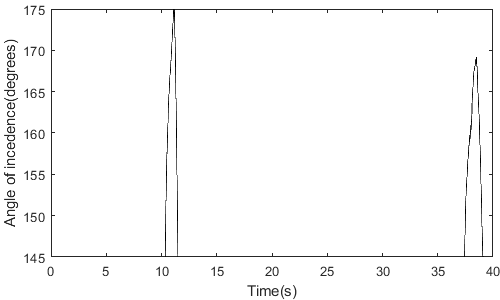

% figure
% plot3(out.pos.Data(1:9000,1),out.pos.Data(1:9000,2),out.alt.Data(:,1:9000),"Color",'red',"LineWidth",2)
% hold on
% plot3(out.pos.Data(9000:45000,1),out.pos.Data(9000:45000,2),out.alt.Data(:,9000:45000),"Color",'green',"LineWidth",2)
% plot3(out.pos.Data(45000:end,1),out.pos.Data(45000:end,2),out.alt.Data(:,45000:end),"Color",'blue',"LineWidth",2)
% legend('Ascent','Maneuver','Landing')
% hold off
% 
% xlabel('North(m)')
% ylabel('East(m)')
% zlabel('Up(m)')
% set(gca,'LooseInset',get(gca,'TightInset'));
% set(gcf, 'Position',  [100, 100, 500, 500])
% 
% figure
% plot(out.alt.Time,out.alt.Data(:),'Color', 'black')
% xlabel('Time(s)')
% ylabel('Altitude(m)')
% set(gca,'LooseInset',get(gca,'TightInset'));
% set(gcf, 'Position',  [100, 100, 500, 200])
% 
% figure
% plot(out.alt.Time,out.pos.Data(:,1),'Color', 'black')
% hold on
% plot(out.alt.Time,out.pos.Data(:,2),'Color', 'black')
% text(27, 20, "North")
% text(14, -20, "East")
% xlabel('Time(s)')
% ylabel('Altitude(m)')
% set(gca,'LooseInset',get(gca,'TightInset'));
% set(gcf, 'Position',  [100, 100, 500, 200])
% 
% figure
% plot(out.machine_states.Time,out.machine_states.Data(:,1),'Color', 'black')
% hold on
% plot(out.machine_states.Time,out.machine_states.Data(:,2),'-.','Color', 'black')
% hold off
% text(4, 2, 'Burn mode')
% text(4, 0.5, 'Altitude hold')
% set(gca,'LooseInset',get(gca,'TightInset'));
% set(gcf, 'Position',  [100, 100, 500, 200])
% 
% figure
% plot(out.climb_rate.Time,out.climb_rate.Data(:,1),'--','Color', 'black')
% hold on
% plot(out.climb_rate.Time,out.climb_rate.Data(:,2),'Color', 'black')
% text(60, -1, 'Actual climb rate')
% text(59.6, -14.5, 'Wanted climb rate')
% xlim([59 63.3])
% ylim([-20 2])
% set(gca,'LooseInset',get(gca,'TightInset'));
% set(gcf, 'Position',  [100, 100, 500, 200])

figure
plot(out.aoi.Time,rad2deg(out.aoi.Data(:)),'Color', 'black')
xlabel("Time(s)")
ylabel("Angle of incedence(degrees)")
axis([0 40 145 175])
set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 300])

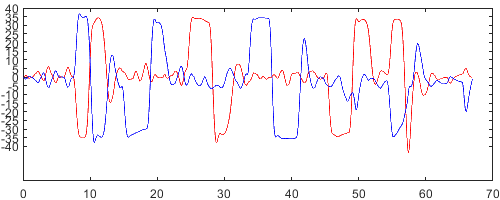


figure
plot(out.pitch.Time,rad2deg(out.pitch.Data(:)),'Color', 'red')
hold on
plot(out.yaw.Time,rad2deg(out.yaw.Data(:)),'Color', 'blue')
yticks(-40:5:40)

set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 200])